clear
fs = 20000 ; % sampling frequency
Nyquis =fs/2 ;
T = 1/(Nyquis) ;
passrip = 2 ; % minimal gain 0 dB +/-2dB
stoppatten = 98 ; % minimal attenuation  -100 +/- 2dB
wp1= 0.2 ; % pass band left border
wp2= 0.3 ; % pass band right border
ws1 = 0.1 ; % stop band left border
ws2 = 0.4; % stop  band right border



bandpassSpecs  =fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2',ws1,wp1,wp2,ws2,stoppatten,passrip,stoppatten) ;
bandpassFilt = design(bandpassSpecs,'butter','matchexactly','passband','SystemObject',true)

bandpassFilt =   dsp.BiquadFilter with properties:

                   Structure: 'Direct form II'
             SOSMatrixSource: 'Property'
                   SOSMatrix: [12×6 double]
                 ScaleValues: [13×1 double]
           InitialConditions: 0
    OptimizeUnityScaleValues: true

  Show all properties


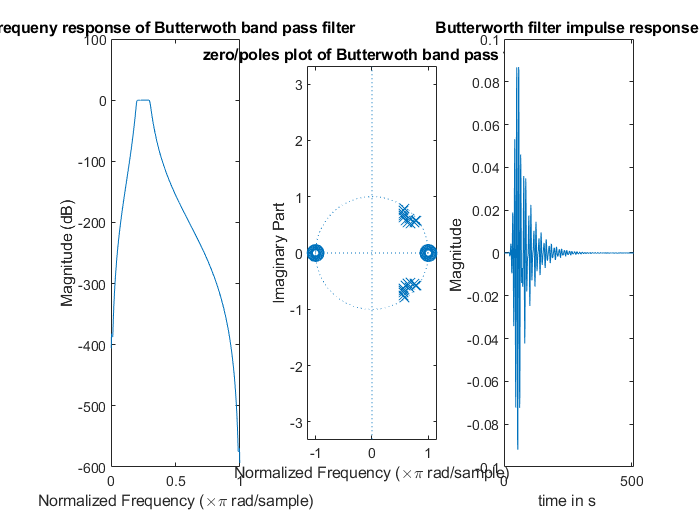

fvtool(bandpassFilt)
[B,A] = tf(bandpassFilt) ;
% compute the Butterworth frquency response 
[H_bw,w_bw]=freqz(B,A) ;
% compute the butterworth impulse response
impulse_bw = impz(B,A) ; 


%---------------Windowing 

% find the maximum amplitude of the impulse response 
M = max(impulse_bw) ; 
for i=1:length(impulse_bw)
    if impulse_bw(i) >  ( 0.1 * M ) 
        effective_impulse(i) = impulse_bw(i) ; 
    end
end
size_10 = 0.90 * length(effective_impulse) ;
size_40 = 0.60 * length(effective_impulse) ;
size_60 = 0.40 * length(effective_impulse) ;
size_75 = 0.25 * length(effective_impulse) ;

%------------ Rectangular window 

w_rect_10 = window(@rectwin ,size_10);
w_rect_40 = window(@rectwin ,size_40);
w_rect_60 = window(@rectwin ,size_60);
w_rect_75 = window(@rectwin ,size_75);


w_rect_10 = zero_padded(w_rect_10,length(effective_impulse)) ; 
w_rect_40 = zero_padded(w_rect_40,length(effective_impulse)) ; 
w_rect_60 = zero_padded(w_rect_60,length(effective_impulse)) ; 
w_rect_75 = zero_padded(w_rect_75,length(effective_impulse)) ; 


impulse_10 = effective_impulse .* w_rect_10; 
impulse_40 = effective_impulse .* w_rect_40 ; 
impulse_60= effective_impulse .* w_rect_60; 
impulse_75 = effective_impulse .* w_rect_75 ; 

%------------- Hamming window 

w_Hamm_10 = window(@hamming ,size_10);
w_Hamm_40 = window(@hamming ,size_40);
w_Hamm_60 = window(@hamming ,size_60);
w_Hamm_75 = window(@hamming ,size_75);

w_Hamm_10 = zero_padded(w_Hamm_10 , length(effective_impulse)) ;
w_Hamm_40 =  zero_padded(w_Hamm_40 , length(effective_impulse)) ;
w_Hamm_60 = zero_padded(w_Hamm_60 , length(effective_impulse)) ;
w_Hamm_75 =  zero_padded(w_Hamm_75 , length(effective_impulse)) ;

impulse_10_ = effective_impulse .* w_Hamm_10 ; 
impulse_40_ = effective_impulse .* w_Hamm_40 ; 
impulse_60_= effective_impulse .* w_Hamm_60 ; 
impulse_75_ = effective_impulse .* w_Hamm_75 ;

%---------frequency responses associated to each shortned impulse response 

%--------Rect windowed frequency responses

effective_freq_response = fft(effective_impulse);
freq_response_10 = fft(impulse_10);
freq_response_40 = fft(impulse_40);
freq_response_60 = fft(impulse_60);
freq_response_75 = fft(impulse_75);

%--------Hamming windowed frequency responses
freq_response_10_ =  fft(impulse_10_);
freq_response_40_ =  fft(impulse_40_);
freq_response_60_ =  fft(impulse_60 );
freq_response_75_ =  fft(impulse_75_);

%------------------------------
% frequency response  plot of the filter
figure()
subplot(1,3,1)
plot(w_bw/pi,20*log10(abs(H_bw)))
title(['frequeny response of Butterwoth band pass filter ' ]);
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

%  zero / pole plot of the filter
z = roots(B) ; 
p = roots(A) ; 
subplot(1,3,2)
zplane(z,p)
title(['zero/poles plot of Butterwoth band pass filter ' ])
xlabel('Normalized Frequency (\times\pi rad/sample)')

%  impulse response plot of the filter
subplot(1,3,3)
plot(impulse_bw)
title(' Butterworth filter impulse response  ')
xlabel('time in s ')
ylabel('Magnitude ')

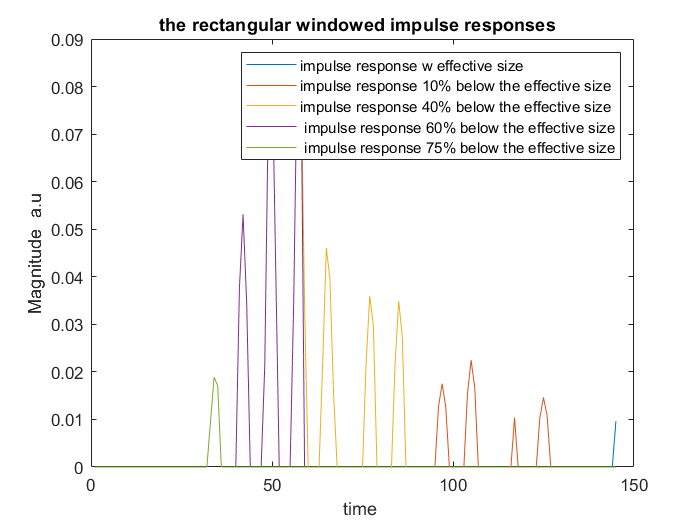


% the shortened impulse responses using the rectangular window

figure()
plot(effective_impulse)
hold on
plot(impulse_10)
plot(impulse_40)
plot(impulse_60)
plot(impulse_75)
title(['the rectangular windowed impulse responses  ' ]);
legend('impulse response w effective size ' ,'impulse response 10% below the effective size ' ,'impulse response 40% below the effective size ' ,' impulse response 60% below the effective size ' ,' impulse response 75% below the effective size '  )
xlabel('time ')
ylabel('Magnitude  a.u')

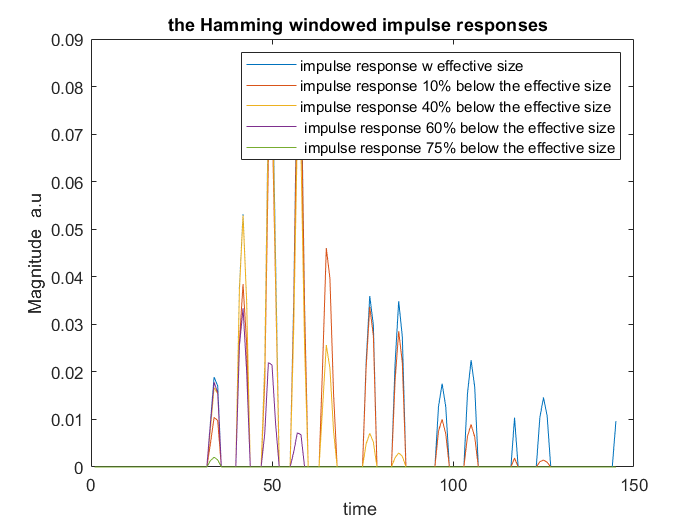



% the shortened impulse responses using the Hamming window

figure()
plot(effective_impulse)
hold on
plot(impulse_10_)
plot(impulse_40_)
plot(impulse_60_)
plot(impulse_75_)
title(['the Hamming windowed impulse responses  ' ]);
legend('impulse response w effective size ' ,'impulse response 10% below the effective size ' ,'impulse response 40% below the effective size ' ,' impulse response 60% below the effective size ' ,' impulse response 75% below the effective size '  )
xlabel('time ')
ylabel('Magnitude  a.u')

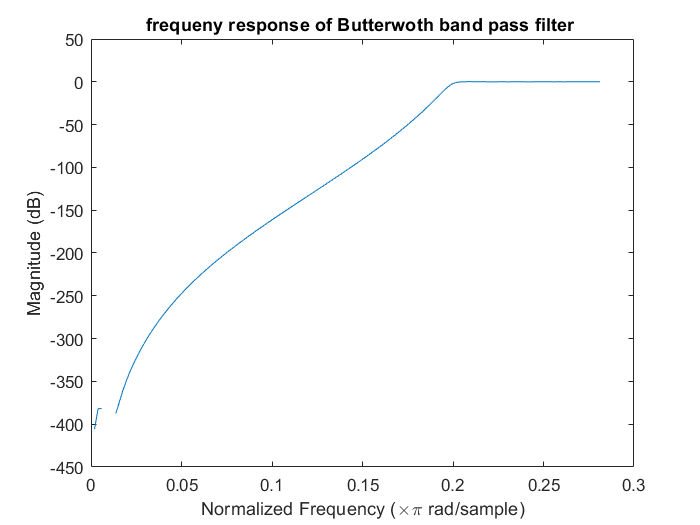


% plotting the frequency responses to see the impact of impulse response
% shortening 

% Rect windowed frequency responses 
% we need to take only the first 145 frequencies amoung the frequency
% vector ( it's the effective impulse response length )

w_bw_ = w_bw(1:145) ;
H_bw_ = H_bw(1:145) ;
% original frequency response within the effective impulse length
figure()
plot(w_bw_/pi,20*log10(abs(H_bw_)))
title(['frequeny response of Butterwoth band pass filter ' ]);
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

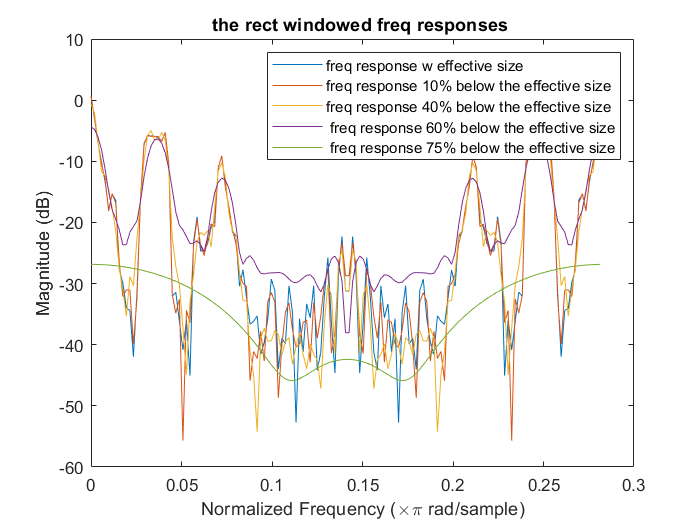



effective_freq_response = zero_padded(effective_freq_response , length(H_bw)) ;
freq_response_10 =  zero_padded(freq_response_10 , length(H_bw)) ;
freq_response_40 = zero_padded(freq_response_40 , length(H_bw)) ;
freq_response_60 =  zero_padded(freq_response_60 , length(H_bw)) ;
freq_response_75 =  zero_padded(freq_response_75 , length(H_bw)) ;

figure()
plot(w_bw/pi , 20*log10(abs(effective_freq_response)))
hold on
plot(w_bw/pi , 20*log10(abs(freq_response_10)))
plot(w_bw/pi , 20*log10(abs(freq_response_40)))
plot(w_bw/pi , 20*log10(abs(freq_response_60)))
plot(w_bw/pi , 20*log10(abs(freq_response_75)))
title(['the rect windowed freq responses ' ]);
legend('freq response w effective size ' ,'freq response 10% below the effective size ' ,'freq response 40% below the effective size ' ,' freq response 60% below the effective size ' ,' freq response 75% below the effective size '  )
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

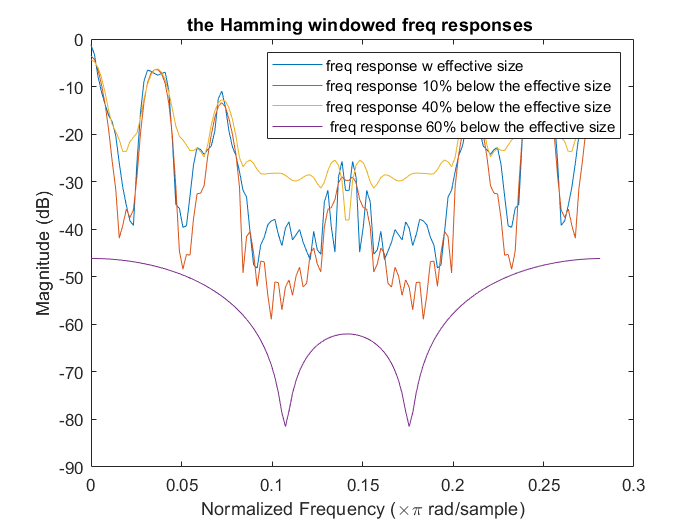


% Hamming windowed frequency responses 

figure()
%plot(w_bw_/pi , 20*log10(abs(effective_freq_response)))

plot(w_bw_/pi , 20*log10(abs(freq_response_10_)))
hold on
plot(w_bw_/pi , 20*log10(abs(freq_response_40_)))
plot(w_bw_/pi , 20*log10(abs(freq_response_60_)))
plot(w_bw_/pi , 20*log10(abs(freq_response_75_)))
title(['the Hamming windowed freq responses ' ]);
legend('freq response w effective size ' ,'freq response 10% below the effective size ' ,'freq response 40% below the effective size ' ,' freq response 60% below the effective size ' ,' freq response 75% below the effective size '  )
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

## 1.2 Shorter and shorter

% the band pass filter ranges from 0 to 5 khz ( gain of 0 dB) , 
% we also know that the cut off frequency is at one third of the normalized
% axis ( so the 5khz are at the one third of the normalized axis ) 

% We can guess the order of the filter from the number of samples , we have
% 601 samples so the filter order is 600 

% We can guess the sampling frequency from the position of the 5 khz cutoff
% frequency on the normalized axis ( 5khz -> pi/3 ,  Fs/2 -> pi , thus Fs
% is 30 Khz ) 
% Now we have all the variables needed to design the FIR filter using the
% frequency equivalence method 

% start by creating the ideal low pass filter 

pass_band = ones(1,100);
stop_band = zeros(1,200);
ideal_low_pass = [stop_band , pass_band,1,pass_band , stop_band]

ideal_low_pass =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


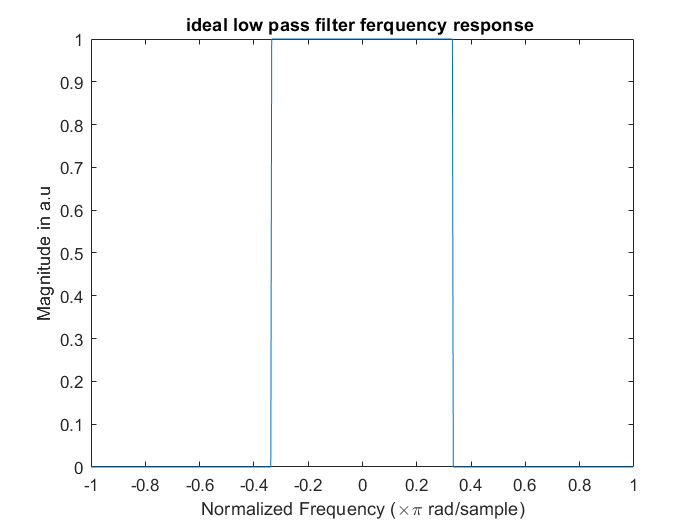

Normalized_freq_vector =-1:2/601:1-(1/601) ;
figure()
plot(Normalized_freq_vector,ideal_low_pass)
title('ideal low pass filter ferquency response ')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude in a.u')

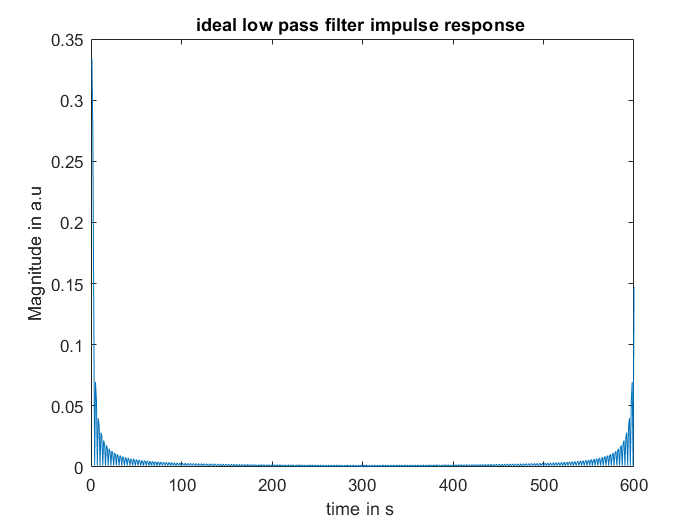


impulse_response = ifft(ideal_low_pass) ; 
figure()
plot(abs(impulse_response))
title('ideal low pass filter impulse response ')
xlabel('time in s ')
ylabel('Magnitude in a.u')
xlim([0 600])


% to see if the immaginary part is small

im_impuluse_response = imag(impulse_response)

im_impuluse_response =          0    0.0014   -0.0014   -0.0000    0.0015   -0.0014   -0.0000    0.0015   -0.0014   -0.0001    0.0015   -0.0014   -0.0001    0.0015   -0.0014   -0.0001    0.0015   -0.0014   -0.0001    0.0015   -0.0014   -0.0001    0.0015   -0.0014   -0.0001    0.0015   -0.0014   -0.0002    0.0015   -0.0013   -0.0002    0.0015   -0.0013   -0.0002    0.0015   -0.0013   -0.0002    0.0015   -0.0013   -0.0002    0.0015   -0.0013   -0.0002    0.0015   -0.0013   -0.0003    0.0016   -0.0013   -0.0003    0.0016


re_impulse_response =real(impulse_response)

re_impulse_response =     0.3344   -0.2762    0.1373    0.0011   -0.0695    0.0546    0.0011   -0.0399    0.0339    0.0011   -0.0281    0.0245    0.0011   -0.0217    0.0191    0.0011   -0.0177    0.0156    0.0011   -0.0150    0.0131    0.0011   -0.0130    0.0113    0.0011   -0.0115    0.0099    0.0011   -0.0103    0.0088    0.0011   -0.0093    0.0079    0.0011   -0.0085    0.0072    0.0011   -0.0078    0.0066    0.0011   -0.0073    0.0060    0.0011   -0.0068    0.0055    0.0011   -0.0063    0.0051    0.0011   -0.0060


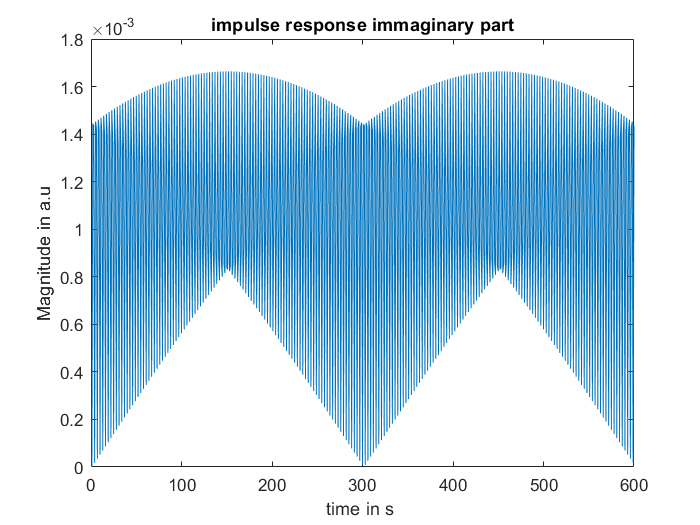

figure()
plot(abs(im_impuluse_response))
title(' impulse response immaginary part ')
xlabel('time in s ')
ylabel('Magnitude in a.u')
xlim([0 600])

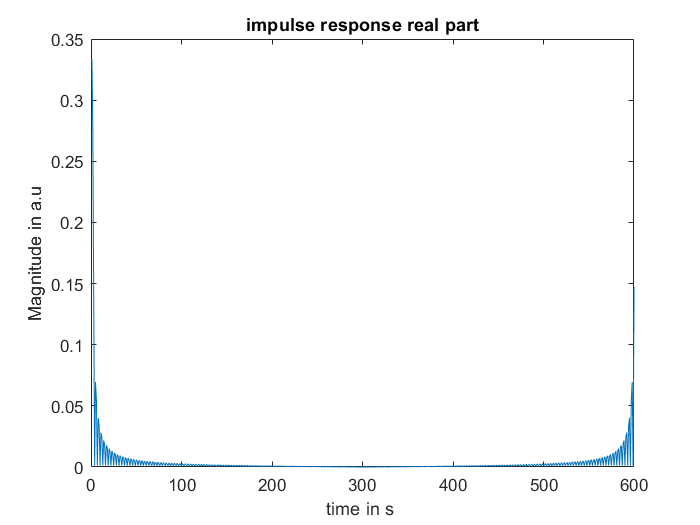


figure()
plot(abs(re_impulse_response))
title(' impulse response real part ')
xlabel('time in s ')
ylabel('Magnitude in a.u')
xlim([0 600])